## **Visualisation des différentes configurations du robot pour suivre une trajectoire avec utilisation des solutions anterieures comme CI pour la cohérence de la traj, Ci rand pour le premier point**

Ce code permet, après definition des variables, des longueurs des bras du robot, de la position desiree de l'effecteur, du nombre de solution souhaités affichées, et des butées de chaque articulation, de générer l'espace de travail du robot, puis de le visualiser dans les configurations possibles pour atteindre le point désiré par résolution de la cinmeatique inverse par la méthode variationnelle. 

### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail

Cette partie procède tout d'abord à une verification de l'appartenance du point désiré de l'effecteur à l'esapce de travail du robot. Si cela est vérifé on lance alors le calcul de cinématique inverse par la méthode variationnelle. 

Puis on affiche les solutions , d'abord en raidan et ensuite en degrès.

### **Definition des variables**

% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du quatrieme bras
a5 = 2; % Longueur du cinquieme bras


theta1_min = -90;
theta1_max = 90;
theta2_min = -95;
theta2_max = 95;
theta3_min = -90;
theta3_max = 90;
theta4_min = -90;
theta4_max = 90;
theta5_min = -90;
theta5_max = 90;

% Stocker les valeurs dans la matrice butee
butee = [theta1_min, theta1_max; theta2_min, theta2_max; theta3_min, theta3_max; theta4_min, theta4_max; theta5_min, theta5_max];
% Enregistrement de la matrice dans un fichier .mat
save('butee.mat', 'butee');
disp('Butées de chaque theta:')

Butées de chaque theta:


disp(butee);

   -90    90
   -95    95
   -90    90
   -90    90
   -90    90



### Definition et affichage de la trajectoire

% Définir la trajectoire souhaitée (par exemple, un cercle)
num_points = 10;
radius = 9;

theta_traj = linspace(0, pi/3, num_points);
x_traj = radius * cos(theta_traj);
y_traj = radius * sin(theta_traj);

% Combiner les coordonnées x et y en une seule matrice de points de trajectoire
trajectory_points = [x_traj', y_traj'];


% Afficher les points de la trajectoire sous forme de tableau
disp('Points de la trajectoire :');

Points de la trajectoire :


fprintf('-------------------------------------------------\n');

-------------------------------------------------


fprintf('| Point  |      X     |      Y     |\n');

| Point  |      X     |      Y     |


fprintf('-------------------------------------------------\n');

-------------------------------------------------


for i = 1:num_points
    fprintf('|   %2d   |   %7.2f   |   %7.2f   |\n', i, x_traj(i), y_traj(i));
end

|    1   |      9.00   |      0.00   |
|    2   |      8.94   |      1.04   |
|    3   |      8.76   |      2.08   |
|    4   |      8.46   |      3.08   |
|    5   |      8.04   |      4.04   |
|    6   |      7.52   |      4.95   |
|    7   |      6.89   |      5.79   |
|    8   |      6.18   |      6.55   |
|    9   |      5.37   |      7.22   |
|   10   |      4.50   |      7.79   |


fprintf('-------------------------------------------------\n')

-------------------------------------------------


### Recuperer les solutions

load('finalresCIRand.mat');
% Affichage des résultats globaux dans un tableau
fprintf('Résultats pour suivre la trajectoire avec comme condition initiale random pour le premier point :\n');

Résultats pour suivre la trajectoire avec comme condition initiale random pour le premier point :


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp (final_results_all_with_CIRand);

    1.0000    1.0000    5.3977    1.3141    0.2031    5.9010    5.2765    9.0000   -0.0000
    1.0000    2.0000    5.3446    1.3413    0.4713    5.7757    5.5225    8.9391    1.0448
    1.0000    3.0000    5.8265    1.1010    0.3741    4.6351    0.9504    8.7574    2.0755
    1.0000    4.0000    5.9388    1.1283    0.3363    4.6562    0.9216    8.4572    3.0782
    1.0000    5.0000    6.0558    1.1231    0.3210    4.6572    0.9729    8.0427    4.0392
    1.0000    6.0000    6.1863    1.0869    0.3213    4.6411    1.0702    7.5194    4.9456
    1.0000    7.0000    0.0366    1.0327    0.3421    4.6219    1.1785    6.8944    5.7851
    1.0000    8.0000    0.1614    1.0048    0.3511    4.6167    1.2326    6.1762    6.5464
    1.0000    9.0000    0.2845    0.9852    0.3554    4.6147    1.2697    5.3744    7.2191
    1.0000   10.0000    0.4071    0.9697    0.3568    4.6138    1.2986    4.5000    7.7942
    2.0000    1.0000    5.2619    0.8880    1.1792    5.2937    0.0743    9.0000    0.0000

### Definir position de l'obstacle

x_min=4;
x_max=6;
y_min=-2;
y_max=0;
% Définir les coordonnées des coins du rectangle représentant l'objet fixe
obstacle_coords = [x_min, y_min; x_min, y_max; x_max, y_max; x_max, y_min];

### Visualisation du robot selon les CI suivant la trajectoire

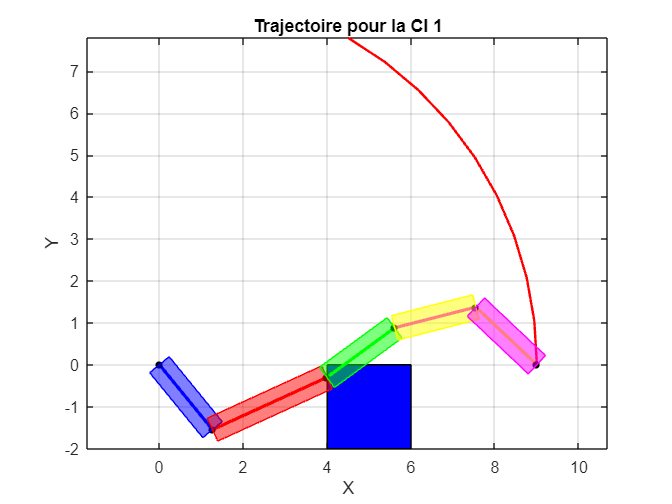

collision


Collision détectée !


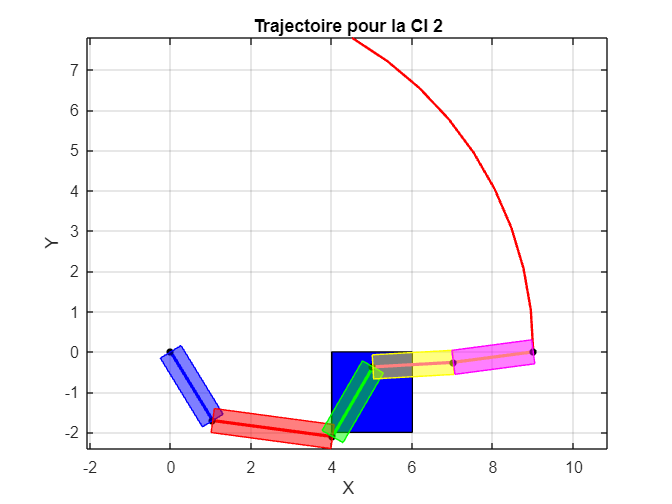

collision


Collision détectée !


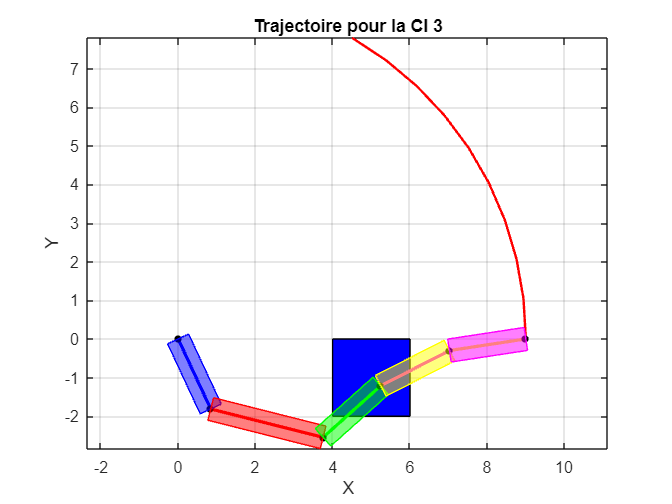

collision


Collision détectée !


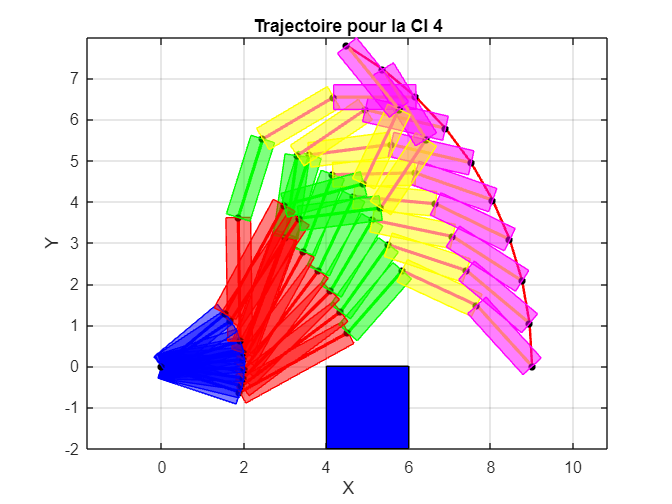

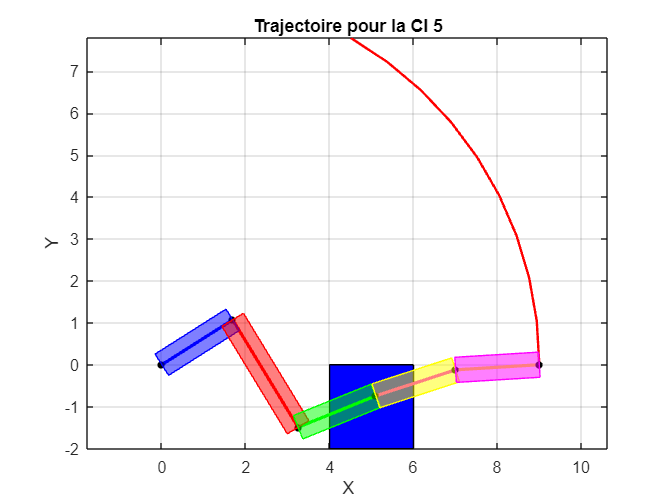

collision


Collision détectée !


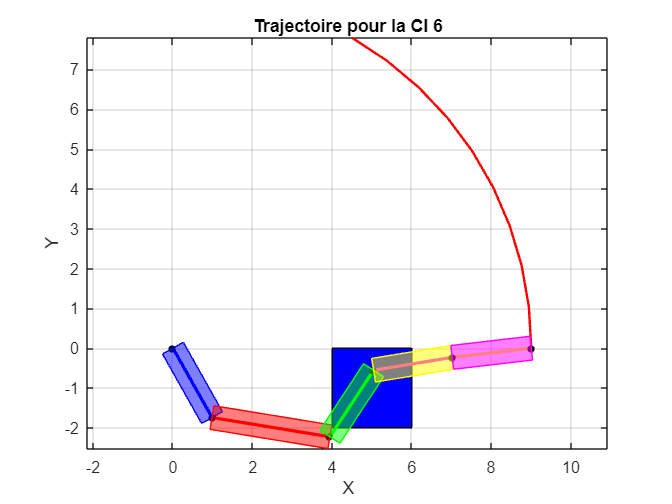

collision


Collision détectée !


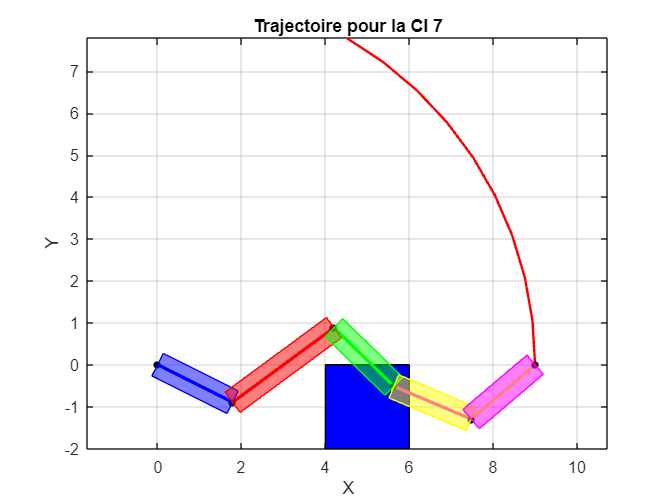

collision


Collision détectée !


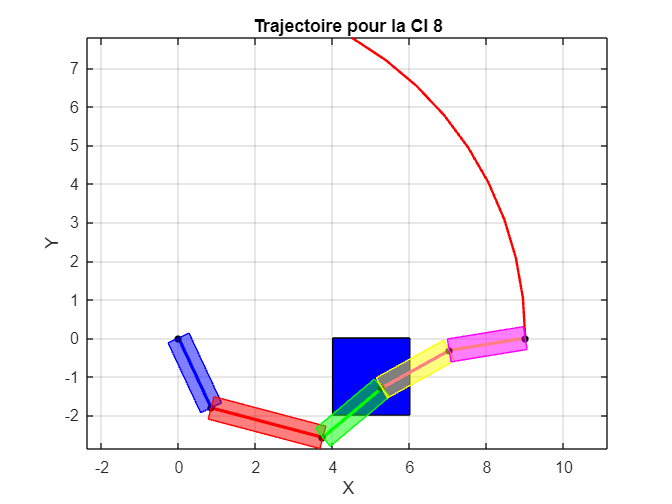

collision


Collision détectée !


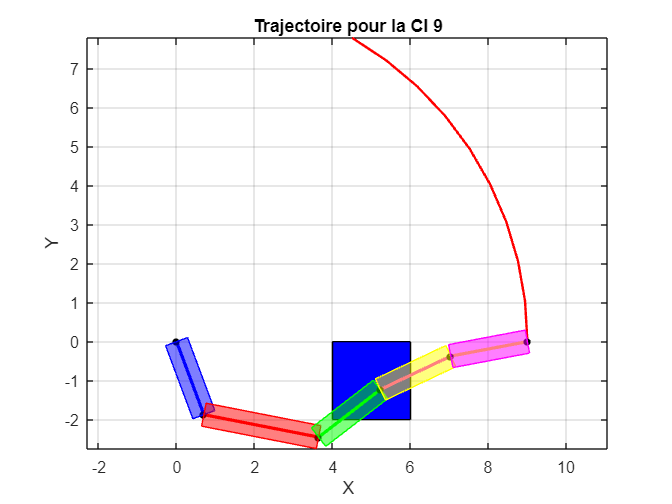

collision


Collision détectée !


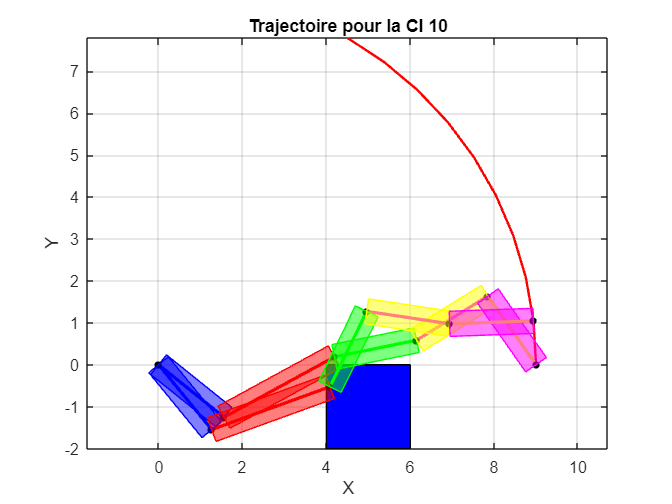

collision


Collision détectée !


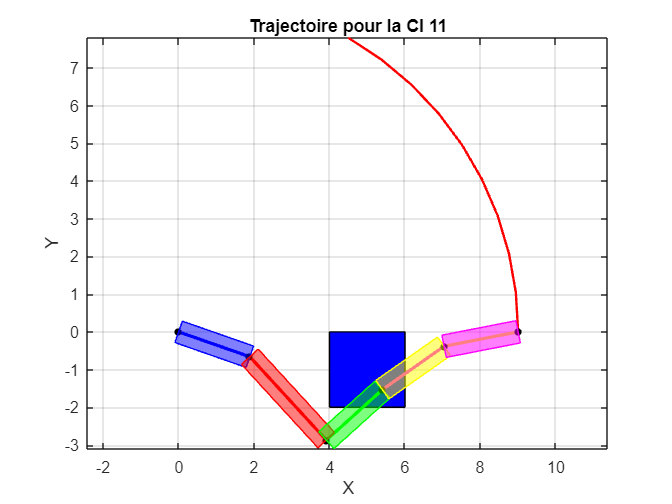

collision


Collision détectée !


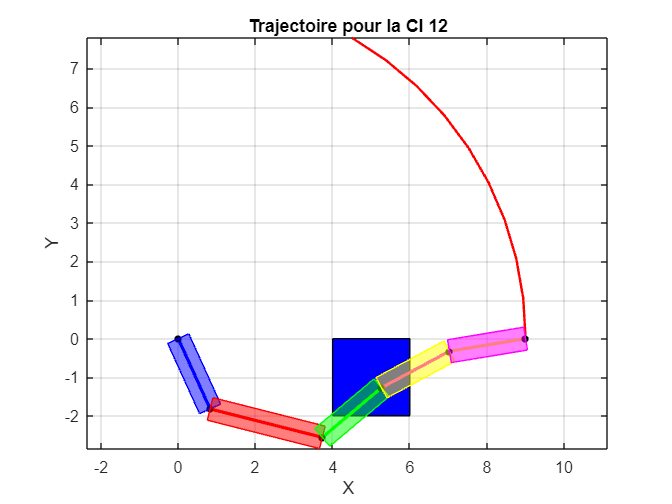

collision


Collision détectée !


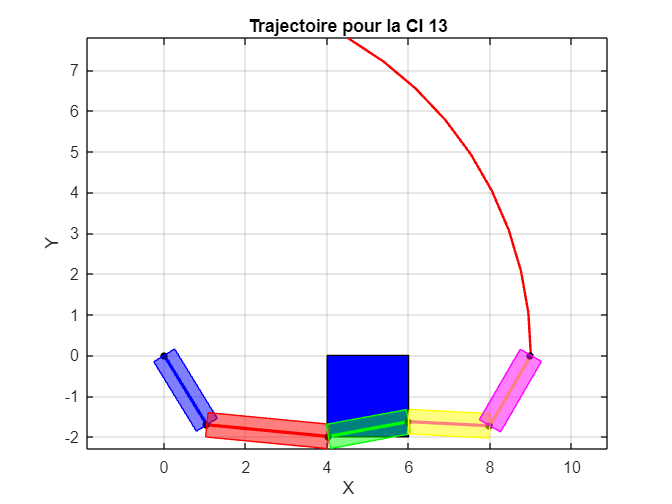

collision


Collision détectée !


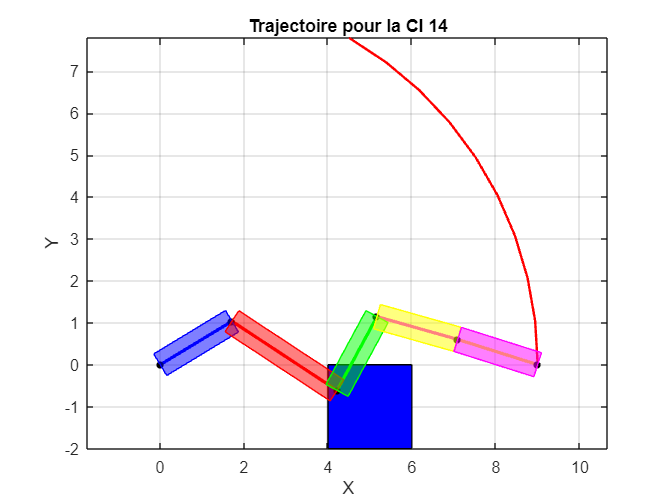

collision


Collision détectée !


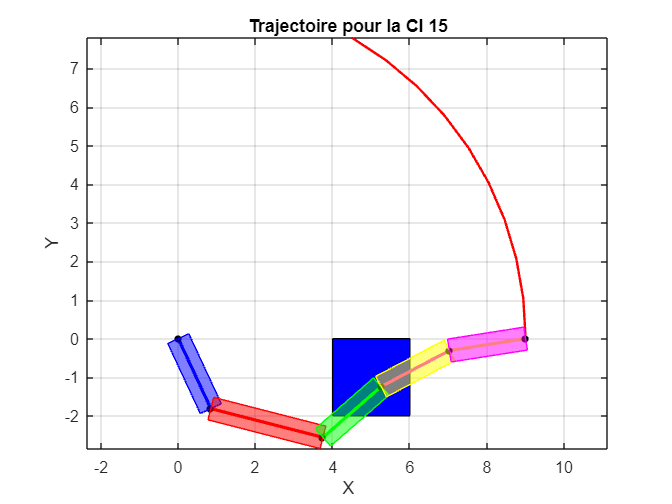

collision


Collision détectée !


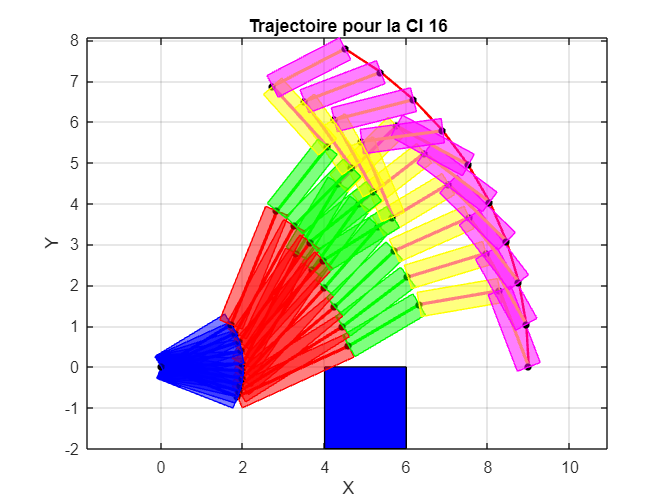

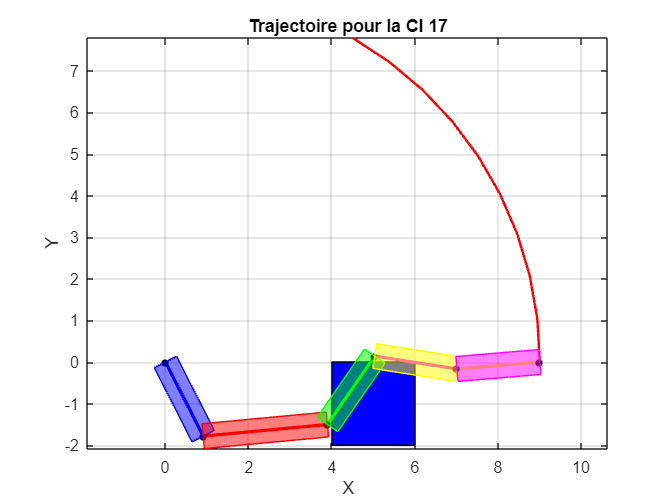

collision


Collision détectée !


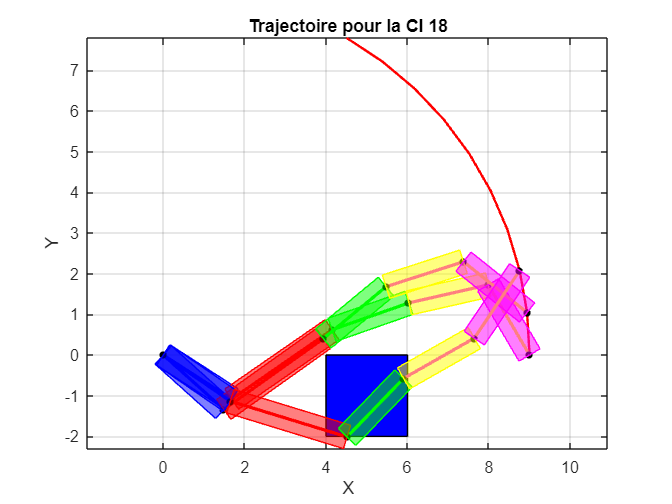

collision


Collision détectée !


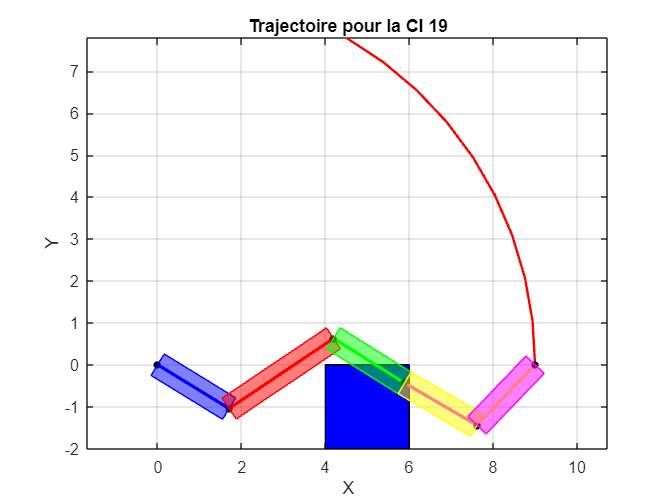

collision


Collision détectée !


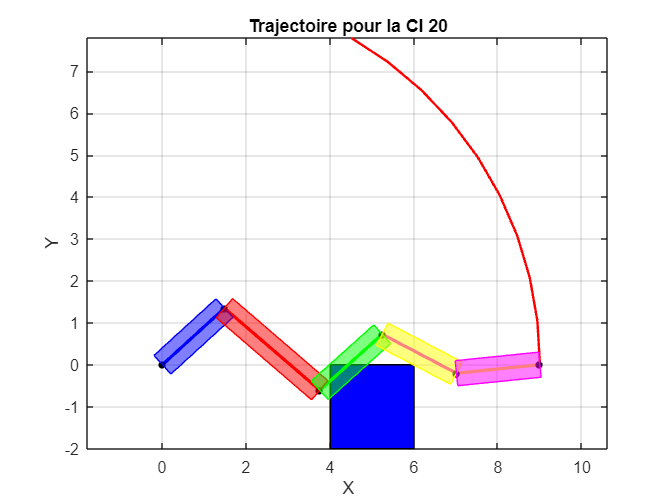

collision


Collision détectée !


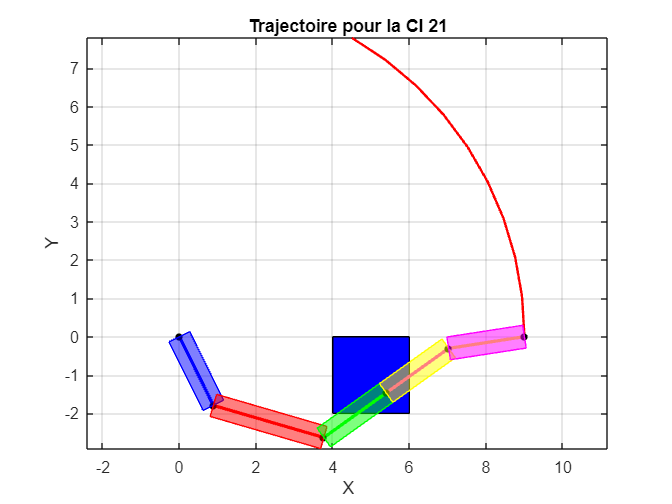

collision


Collision détectée !


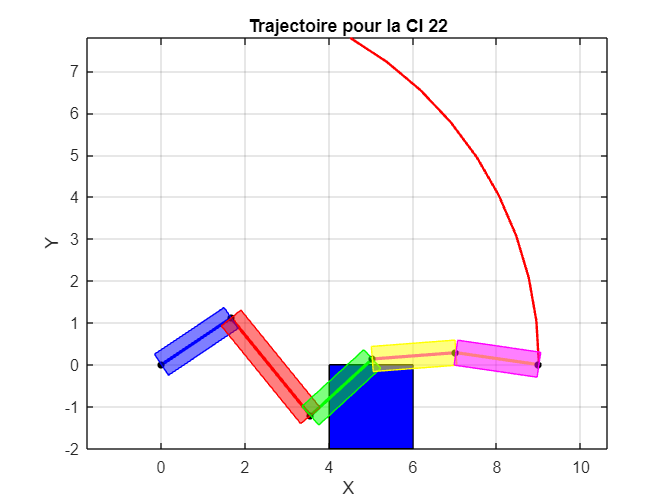

collision


Collision détectée !


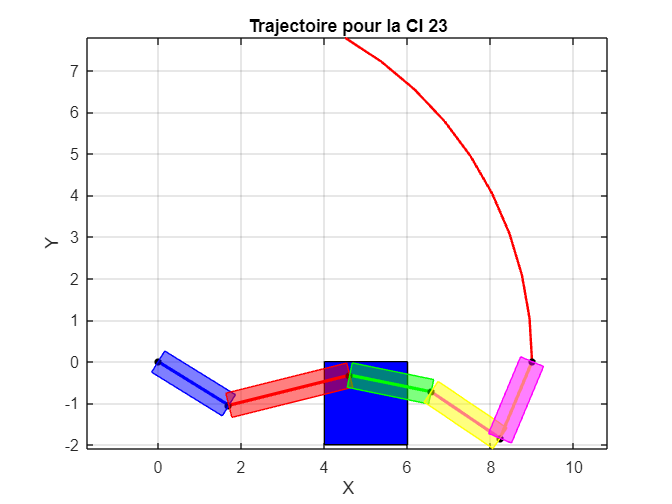

collision


Collision détectée !


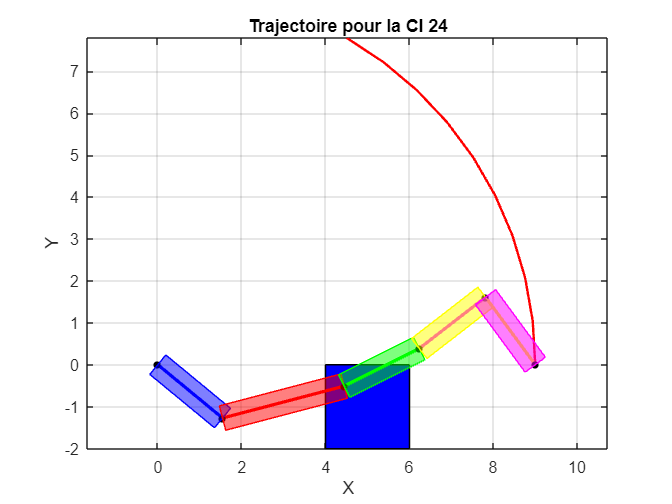

collision


Collision détectée !


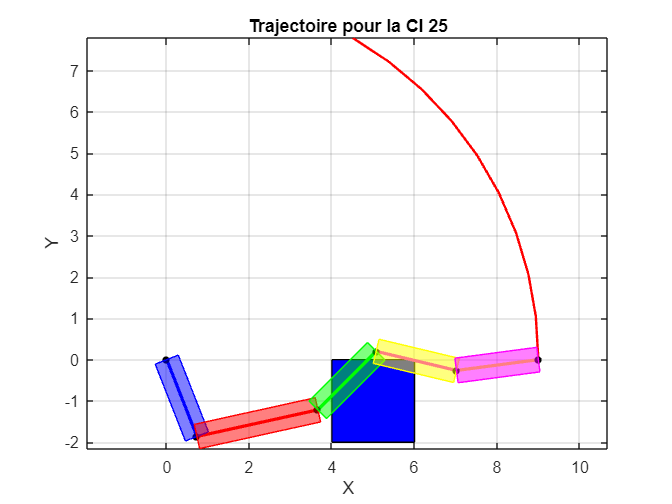

collision


Collision détectée !


% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC
color_segment_CD = 'm'; % Segment CD
color_segment_DE = 'y'; % Segment DE
load("CInumber.mat")

% Pour chaque configuration initiale
for ci = 1:max(CI_numbers)
    % Extraire les indices correspondant à cette configuration initiale
    indices = final_results_all_with_CIRand(:, 1) == ci;

    % Extraire les données pour cette configuration initiale
    data_for_ci = final_results_all_with_CIRand(indices, :);

    % Indicateur de collision pour cette configuration initiale
    collision_detected = false;

    % Afficher la trajectoire
    figure;
    plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
    axis equal; % Pour que l'échelle des axes soit égale
    xlabel('X');
    ylabel('Y');
    title(['Trajectoire pour la CI ', num2str(ci)]);
    grid on;
    hold on;
    rectangle('Position', [x_min, y_min, x_max - x_min, y_max - y_min], ...
          'EdgeColor', 'k', 'FaceColor', 'b');
    % Pour chaque point de la trajectoire pour cette configuration initiale
    for i = 1:size(data_for_ci, 1)
        % Extraire les angles d'articulation pour ce point de la trajectoire
        theta1 = data_for_ci(i, 3);
        theta2 = data_for_ci(i, 4);
        theta3 = data_for_ci(i, 5);
        theta4 = data_for_ci(i, 6);
        theta5 = data_for_ci(i, 7);

        % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
        O = [0, 0]; % Position de l'origine
        A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
        B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
        C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
        D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
        E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
        
        % Matrice des segments du robot
        segments_robot = {[O; A], [A; B], [B; C], [C; D], [D; E]};

        
        % Tracer le robot pour ce point de la trajectoire
        plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'HandleVisibility', 'off'); % Segment OA
        plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'HandleVisibility', 'off'); % Segment AB
        plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'HandleVisibility', 'off'); % Segment BC
        plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'HandleVisibility', 'off'); % Segment CD
        plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'HandleVisibility', 'off'); % Segment DE
        scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'HandleVisibility', 'off'); % Marques pour les articulations
        
        % Ajouter des rectangles autour des segments
        rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
        drawSegmentRectangle(O, A, rectWidth, 'b');
        drawSegmentRectangle(A, B, rectWidth, 'r');
        drawSegmentRectangle(B, C, rectWidth, 'g');
        drawSegmentRectangle(C, D, rectWidth, 'y');
        drawSegmentRectangle(D, E, rectWidth, 'm');
        
        % Vérifier la collision pour chaque segment du robot
        
        for j = 1:numel(segments_robot)-1
            segment = [segments_robot{j}; segments_robot{j+1}];
            collision_detected = checkCollisionSegmentObstacle(segment, obstacle_coords);
            if collision_detected
                disp('Collision détectée !');
                break; % Sortir de la boucle dès qu'une collision est détectée
            end
        end

        if collision_detected
            break; % Sortir de la boucle principale dès qu'une collision est détectée
        end

        % Mettre en pause pour une durée appropriée
        pause(0.1); % Changer cette valeur pour ajuster la vitesse de l'animation
    end
end

### Variations de chaque angle pour chaque solution


% % Affichage des variations de chaque angle pour chaque solution
% figure;
% % Initialiser un tableau pour stocker les couleurs uniques
% unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
% color_index = 1;
% 
% % Choisir une carte de couleurs
% custom_colormap = parula(size(CI_angles_radians, 1));
% %carte de couleurs basée sur la taille de la matrice point1_solutions. Chaque ligne de point1_solutions représente une 
% % configuration initiale, et une couleur différente sera utilisée pour chaque configuration.
% 
% for joint = 1:5
%      % Créer un subplot pour chaque angle d'articulation
%     subplot(2, 3, joint);
% 
%     % Titre de subplot
%     title(['Variation de Theta', num2str(joint), ' pour chaque CI']);
%     xlabel('Point de trajectoire');
%     ylabel(['Theta', num2str(joint)]);
%     hold on;
%     % Extraire les données pour cet angle (colonne joint+2 car la première colonne est le numéro du point de trajectoire)
%     data_for_joint = final_results_all_without_collision(:, joint+2);
% 
%        % Récupérer les couleurs uniques
%     unique_colors = unique(final_results_all_without_collision(:, 1));
%     % Parcourir les couleurs et les étiqueter dans la légende
%     for i = 1:length(unique_colors)
%         scatter(NaN, NaN, 10, custom_colormap(i, :), 'filled', 'DisplayName', ['CI ', num2str(unique_colors(i))]);
%     end
%     % Regrouper les indices des points par CI
%     grouped_indices = {};
%     for i = 1:length(unique_colors)
%         indices = find(final_results_all_without_collision(:, 1) == unique_colors(i));
%         grouped_indices{i} = indices;
%     end
% 
% 
%    % Tracer une ligne reliant les points de chaque CI avec interpolation linéaire
%     for i = 1:length(grouped_indices)
%         indices = grouped_indices{i};
%         sorted_data = sortrows([final_results_all_without_collision(indices, 2), data_for_joint(indices)]);
% 
%         % Tracer les points
%         scatter(sorted_data(:, 1), sorted_data(:, 2), 10, custom_colormap(i, :), 'filled', 'HandleVisibility', 'off');
% 
%         % Tracer la courbe d'interpolation linéaire
%         x = sorted_data(:, 1);
%         y = sorted_data(:, 2);
%         interpolated_y = interp1(x, y, x, 'linear');
%         plot(x, interpolated_y, '-', 'Color', custom_colormap(i, :), 'LineWidth', .5, 'HandleVisibility', 'off');
%     end
% 
% end
% 
% % Ajouter une légende indiquant à quelle CI chaque couleur correspond
% legend('show');

% Vérifier la collision entre un segment et un obstacle

function collision_detected = checkCollisionSegmentObstacle(segment, obstacle_coords)
    % Extraire les coordonnées des points du segment
    x1 = segment(1, 1);
    y1 = segment(1, 2);
    x2 = segment(2, 1);
    y2 = segment(2, 2);

    % Pour chaque côté de l'obstacle
    for i = 1:size(obstacle_coords, 1)
        % Extraire les coordonnées des points du côté de l'obstacle
        x3 = obstacle_coords(i, 1);
        y3 = obstacle_coords(i, 2);
        if i < size(obstacle_coords, 1)
            x4 = obstacle_coords(i+1, 1);
            y4 = obstacle_coords(i+1, 2);
        else
            x4 = obstacle_coords(1, 1);
            y4 = obstacle_coords(1, 2);
        end

        % Vérifier s'il y a intersection entre le segment et le côté de l'obstacle
        collision_detected = doIntersect(x1, y1, x2, y2, x3, y3, x4, y4);
        if collision_detected
            disp('collision');
            return; % Si une collision est détectée, sortir de la fonction
        end
    end

    % Aucune collision détectée
    collision_detected = false;
end

% Vérifier s'il y a intersection entre deux segments de ligne
function intersect = doIntersect(x1, y1, x2, y2, x3, y3, x4, y4)
    % Calculer les orientations
    orientation1 = (y2 - y1) * (x3 - x2) - (x2 - x1) * (y3 - y2);
    orientation2 = (y2 - y1) * (x4 - x2) - (x2 - x1) * (y4 - y2);
    orientation3 = (y4 - y3) * (x1 - x4) - (x4 - x3) * (y1 - y4);
    orientation4 = (y4 - y3) * (x2 - x4) - (x4 - x3) * (y2 - y4);

    % Vérifier s'il y a intersection
    intersect = (orientation1 * orientation2 < 0) & (orientation3 * orientation4 < 0);
end

function in_workspace = point_in_workspace(x, y, points_atteign, K)
    % Vérifie si le point (x, y) est dans l'espace de travail du robot
    in_workspace = inpolygon(x, y, points_atteign(K, 1), points_atteign(K, 2));
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, theta_prev)

    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
    
    % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];
    
     % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        
        
        % Initialiser les angles d'articulation avec les valeurs précédentes
        theta1 = theta_prev(1);
        theta2 = theta_prev(2);
        theta3 = theta_prev(3);
        theta4 = theta_prev(4);
        theta5 = theta_prev(5);

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))));

            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
                 dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Mettre à jour les angles d'articulation précédents pour le prochain point de trajectoire
            theta_prev = [theta1, theta2, theta3, theta4, theta5];
            
            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
        end
    end
end
